# Explanation

% This program computes 1 set of 4 RSS from each of the four BS

## **To do**

% For the project, you need to augment the program:
% 1. Implement the handoff algorithms that use RSS1,2,3,4 as inputs
% 2. Include a loop so that you can have 100 sets of the 4 RSS
% (Hint: RSS of different sets only differ due to the
% random variable of shadow fading)
% 3. In the loop store variable data between iterations
% that will be used to make the final histograms/PDFs

### **prepared code**

clc;
clear;
% Declare the various variables used for distances
R = 250;
L = 2 * R;
speed = 1;
sample_time = 0.1;
step_distance = speed * sample_time;
g = 150;
min_distance = sqrt(g);
max_distance = L - sqrt(g);
d1 = min_distance:step_distance:max_distance;
d2 = L - d1;
d3 = abs(R - d1);
d4 = abs(R - d1);
Ns = length(d1);
% Declare variables and compute RSS
% Part 1: Computations independant of the random variable
% for shadow fading
Pt = 20;
Po = 38;
grad1 = 2;
grad2 = 2;
alpha = exp(-1/85);
sigma1 = sqrt(8);
sigma2 = sqrt(sigma1^2 * (1 - alpha^2));
RSS01 = Pt - Po - (10 * grad1 * log10(d1) + 10 * grad2 * log10(d1/g));
RSS02 = Pt - Po - (10 * grad1 * log10(d2) + 10 * grad2 * log10(d2/g));
RSS_corner = Pt - Po - (10 * grad1 * log10(R) + 10 * grad2 * log10(R/g));
RSS03 = RSS_corner - (10 * grad1 * log10(d3) + 10 * grad2 * log10(d3/g));
RSS04 = RSS_corner - (10 * grad1 * log10(d4) + 10 * grad2 * log10(d4/g));
for i=1:Ns
    if d3(i) < min_distance
        RSS03(i) = RSS_corner;
    end
    if d4(i) < min_distance
        RSS04(i) = RSS_corner;
    end
end
% Part 2: Adding the random variable for shadow fading
RSS = zeros(4,Ns,100);
s1 = zeros(1,Ns);
s2 = zeros(1,Ns);
s3 = zeros(1,Ns);
s4 = zeros(1,Ns);
for j=1:100
    s1(1) = sigma1 * randn(1);
    s2(1) = sigma1 * randn(1);
    s3(1) = sigma1 * randn(1);
    s4(1) = sigma1 * randn(1);
    for i=2:Ns
        s1(i) = alpha * s1(i-1) + sigma2 * randn(1);
        s2(i) = alpha * s2(i-1) + sigma2 * randn(1);
        s3(i) = alpha * s3(i-1) + sigma2 * randn(1);
        s4(i) = alpha * s4(i-1) + sigma2 * randn(1);
    end
    RSS(1,:,j) = RSS01 + s1;
    RSS(2,:,j) = RSS02 + s2;
    RSS(3,:,j) = RSS03 + s3;
    RSS(4,:,j) = RSS04 + s4;
end

% Plot the RSS values obtained
figure(1)
plot(d1, RSS(1,:,1),'r')
hold on
plot(d1, RSS(2,:,1),'b')
hold on
plot(d1, RSS(3,:,1),'g')
hold on
plot(d1, RSS(4,:,1),'c')
title('RSS versus distance along route')
xlabel('distance from BS1 in meters');
ylabel('dBm');
legend('RSS1','RSS2','RSS3','RSS4')

# **Simulation**

N_Handoff_simple = zeros(1,100);
N_Handoff_threshold = zeros(1,100);
N_Handoff_hysteresis = zeros(1,100);
N_Handoff_hysteresis_threshold = zeros(1,100);
Location_Handoff_simple = cell(1,100);
Location_Handoff_threshold = cell(1,100);
Location_Handoff_hysteresis = cell(1,100);
Location_Handoff_hysteresis_threshold = cell(1,100);
for j = 1:100
    [N_Handoff_simple(j),Location_Handoff_simple{1,j}] = SimpleRSS(RSS(:,:,j), d1)
    [N_Handoff_threshold(j),Location_Handoff_threshold{1,j}] = ThresholdRSS(RSS(:,:,j),d1)
    [N_Handoff_hysteresis(j),Location_Handoff_hysteresis{1,j}] = HysteresisRSS(RSS(:,:,j),d1)
    [N_Handoff_hysteresis_threshold(j),Location_Handoff_hysteresis_threshold{1,j}] = Hysteresis_Threshold_RSS(RSS(:,:,j),d1)
end

#### PDF of Number of handoffs for the four algorithms

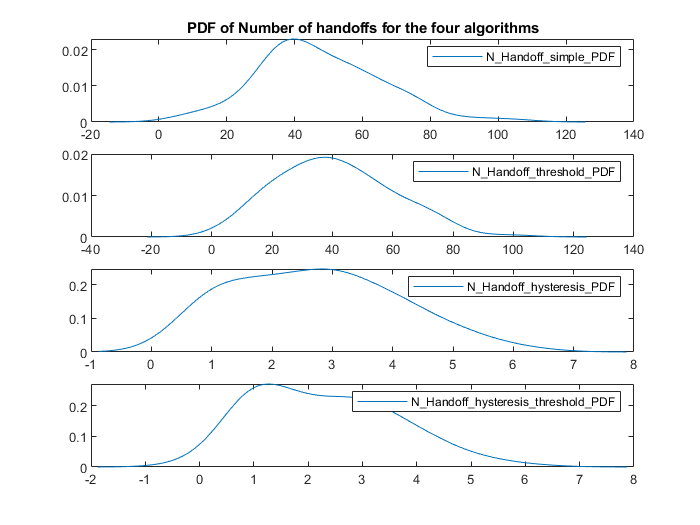

[f_N_simple,x_N_simple] = ksdensity(N_Handoff_simple);
subplot(4,1,1)
plot(x_N_simple,f_N_simple)
title('PDF of Number of handoffs for the four algorithms')
legend('N\_Handoff\_simple\_PDF')
[f_N_threshold,x_N_threshold] = ksdensity(N_Handoff_threshold);
subplot(4,1,2)
plot(x_N_threshold,f_N_threshold)
legend('N\_Handoff\_threshold\_PDF')

[f_N_hysteresis,x_N_hysteresis] = ksdensity(N_Handoff_hysteresis);
subplot(4,1,3)
plot(x_N_hysteresis,f_N_hysteresis)
legend('N\_Handoff\_hysteresis\_PDF')

[f_N_hysteresis_threshold,x_N_hysteresis_threshold] = ksdensity(N_Handoff_hysteresis_threshold);
subplot(4,1,4)
plot(x_N_hysteresis_threshold,f_N_hysteresis_threshold)
legend('N\_Handoff\_hysteresis\_threshold\_PDF')

#### PDF of handoff's location

% approach 1 : using "cellfun" with ksdensity 

% pdf_simple = cellfun(@ksdensity, Location_Handoff_simple, 'UniformOutput', false);
% pdf_threshold = cellfun(@ksdensity, Location_Handoff_threshold, 'UniformOutput', false);
% pdf_hysteresis = cellfun(@ksdensity, Location_Handoff_hysteresis, 'UniformOutput', false);
% pdf_hysteresis_threshold = cellfun(@ksdensity, Location_Handoff_hysteresis_threshold, 'UniformOutput', false);


% approach 2 : using "cellfun" with normpdf 

% mu = 0;
% sigma = 1;
% pdf_simple = cellfun(@(x) normpdf(x, mu, sigma), Location_Handoff_simple, 'UniformOutput', false);
% pdf_threshold = cellfun(@(x) normpdf(x, mu, sigma), Location_Handoff_threshold, 'UniformOutput', false);
% pdf_hysteresis = cellfun(@(x) normpdf(x, mu, sigma), Location_Handoff_hysteresis, 'UniformOutput', false);
% pdf_hysteresis_threshold = cellfun(@(x) normpdf(x, mu, sigma), Location_Handoff_hysteresis_threshold, 'UniformOutput', false);


% approach 3 : using for loop

f_L_simple = cell(1,100);
f_L_threshold = cell(1,100);
f_L_hysteresis = cell(1,100);
f_L_hysteresis_threshold = cell(1,100);

x_L_simple = cell(1,100);
x_L_threshold = cell(1,100);
x_L_hysteresis = cell(1,100);
x_L_hysteresis_threshold = cell(1,100);

for i=1:100
    [f_L_simple{i}, x_L_simple{i}] = ksdensity(Location_Handoff_simple{i})
    [f_L_threshold{i}, x_L_threshold{i}] = ksdensity(Location_Handoff_threshold{i})
    [f_L_hysteresis{i}, x_L_hysteresis{i}] = ksdensity(Location_Handoff_hysteresis{i})
    [f_L_hysteresis_threshold{i}, x_L_hysteresis_threshold{i}] = ksdensity(Location_Handoff_hysteresis_threshold{i})
end

f_L_simple = 1×100 cell array
    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_simple = 1×100 cell array
    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_threshold = 1×100 cell array
    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

x_L_threshold = 1×100 cell array
    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double} 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doub

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 doubl

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 dou

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}   

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}  

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}    

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double} 

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double} 

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0×0 double}

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}    {0

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}  

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double}  

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 double

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 doubl

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    {0×0 doubl

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}    

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 double}

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 doub

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 doub

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 dou

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {0×0 dou

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

f_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

x_L_simple = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 doubl

f_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

x_L_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 do

f_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

x_L_hysteresis = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 d

f_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

x_L_hysteresis_threshold = 1×100 cell array
    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}  

#### plotting the pdf of first simulation of every four algorithm

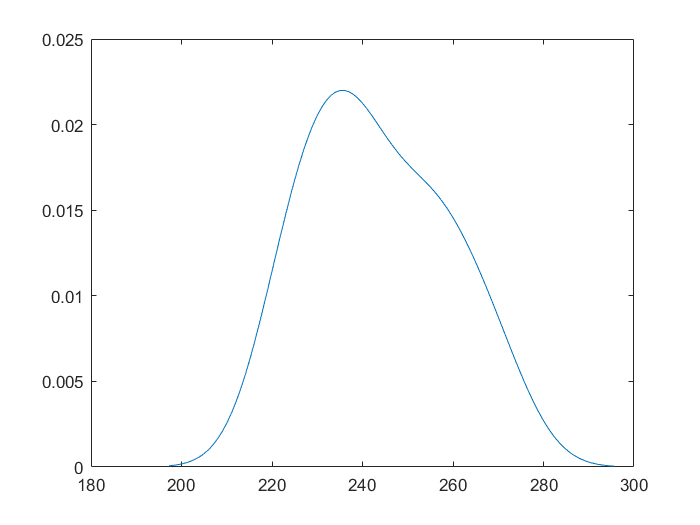

plot(x_L_simple{1},f_L_simple{1})

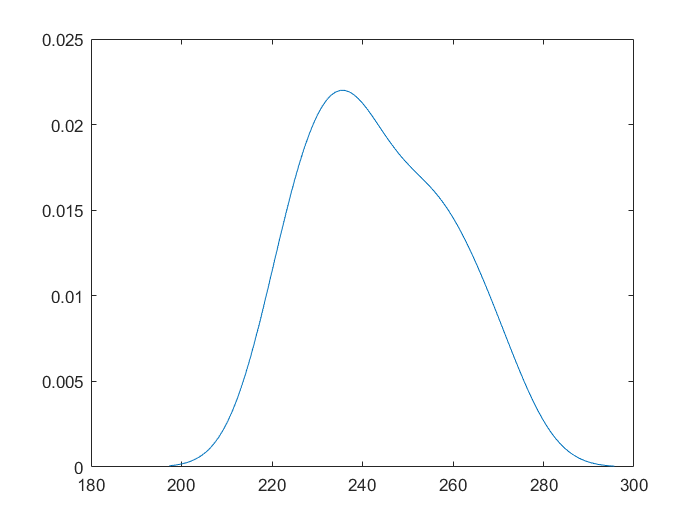

plot(x_L_threshold{1},f_L_threshold{1})

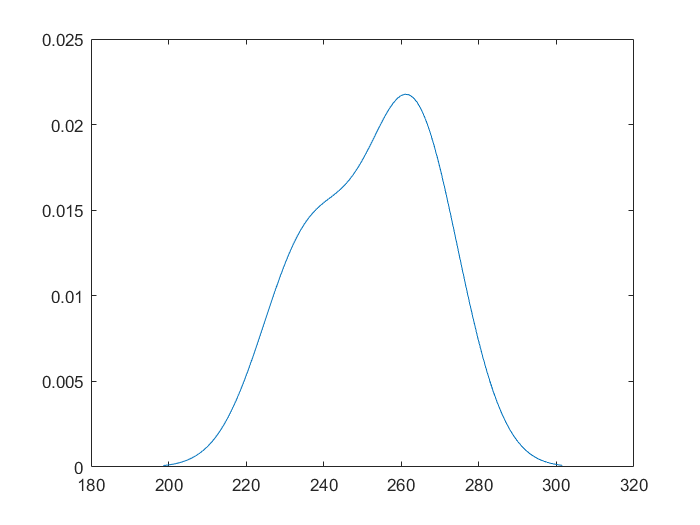

plot(x_L_hysteresis{1},f_L_hysteresis{1})

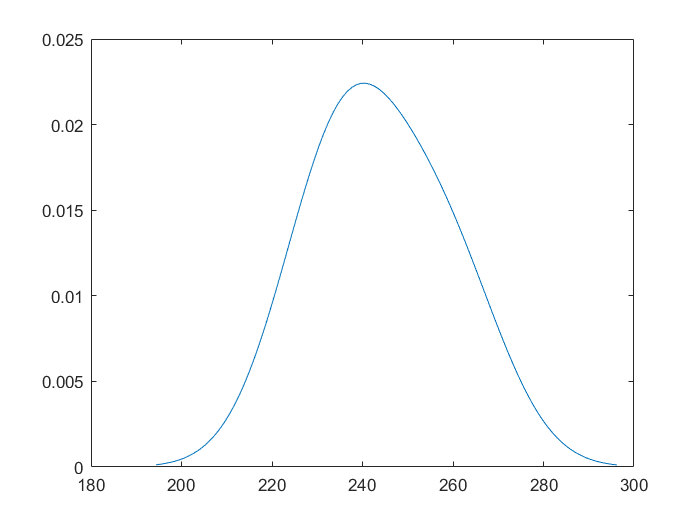

plot(x_L_hysteresis_threshold{1},f_L_hysteresis_threshold{1})